# Péndulo de Furuta

Modelo en espacio de estados

m1 = 0.003492;
m2 = 0.003208;
L1 = 80e-3;
L2 = 180e-3;
J1hat = 14e-6;
J2hat = 37.7e-6;
J0hat = J1hat + m2*L1^2;
b1 = 1e-6 * 180/pi; % Nm/(deg/s) --> Nm/(pi/180 rad/s) = 180/pi Nms
b2 = 1e-6 * 180/pi;
g = 9.81;

Aden = (4*J0hat*J2hat - m2^2*L1^2*L2^2);

A31 = 0;
A32 = g*m2^2*L1*L2^2 / Aden;
A33 = -4*b1*J2hat / Aden;
A34 = -2*b2*m2*L1*L2 / Aden;

A41 = 0;
A42 = 2*g*m2*L2*J0hat / Aden;
A43 = -2*b1*m2*L1*L2/ Aden;
A44 = -4*b2*J0hat / Aden;

B31 = 4*J2hat / Aden;
B41 = 2*m2*L1*L2 / Aden;

A = [0 0 1 0; 0 0 0 1; A31 A32 A33 A34; A41 A42 A43 A44];
B = [0; 0; B31; B41] / 1000;
C = [1 0 0 0];

ts = 1e-2;
sys = ss(A,B,C,0)

sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0   85.15  -2.811  -1.722
   x4       0   127.3  -1.722  -2.575
 
  B = 
          u1
   x1      0
   x2      0
   x3  49.07
   x4  30.06
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sysd = c2d(sys, ts)

sysd =
 
  A = 
               x1          x2          x3          x4
   x1           1    0.004186    0.009861  -7.067e-05
   x2           0       1.006  -8.468e-05    0.009894
   x3           0      0.8306      0.9724    -0.01262
   x4           0       1.252     -0.0168       0.981
 
  B = 
             u1
   x1  0.002423
   x2  0.001478
   x3    0.4817
   x4    0.2933
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



Controlabilidad

Co = ctrb(A,B)

Co = 	1.0e+04 *

         0    0.0049   -0.0190    0.3372
         0    0.0030   -0.0162    0.4571
    0.0049   -0.0190    0.3372   -3.1140
    0.0030   -0.0162    0.4571   -3.8190


unco = length(A) - rank(Co)

unco = 0

Observabilidad

Ob = obsv(A,C)

Ob =     1.0000         0         0         0
         0         0    1.0000         0
         0   85.1465   -2.8114   -1.7224
         0 -458.6357   10.8706   94.4242


unobsv = length(A) - rank(Ob)

unobsv = 0

Realimentación de estados

[K, S, e] = lqr(A, B, diag([1,1,1,1]), eye(1))

K =    -1.0000   43.6421   -1.3403    4.5124


S =     1.2830   -5.3952    0.3214   -0.5578
   -5.3952  118.2895   -6.2550   11.6611
    0.3214   -6.2550    0.3663   -0.6425
   -0.5578   11.6611   -0.6425    1.1988


e =   -0.9990 + 0.0000i
  -7.6594 + 1.9813i
  -7.6594 - 1.9813i
 -58.9572 + 0.0000i


A_ = [A, zeros(size(C')); -C, zeros(size(C, 1))]

A_ =          0         0    1.0000         0         0
         0         0         0    1.0000         0
         0   85.1465   -2.8114   -1.7224         0
         0  127.2950   -1.7224   -2.5751         0
   -1.0000         0         0         0         0


B_ = [B; zeros(size(C,1), size(B,2))]

B_ =          0
         0
   49.0676
   30.0622
         0


C_ = [C, zeros(size(C, 1))]

C_ =      1     0     0     0     0



alpha = 1

alpha = 1

rho = alpha/10

rho = 0.1000


A_zeta = 1./rho .* (alpha .* eye(size(A_,1)) + A_)

A_zeta = 	1.0e+03 *

    0.0100         0    0.0100         0         0
         0    0.0100         0    0.0100         0
         0    0.8515   -0.0181   -0.0172         0
         0    1.2730   -0.0172   -0.0158         0
   -0.0100         0         0         0    0.0100


B_zeta = 1/rho * B_

B_zeta =          0
         0
  490.6764
  300.6220
         0


Q = diag([1 7 1 7 0.5]);
R = 1;
[K_, S_, e_] = lqr(A_zeta, B_zeta, Q, R)

K_ =    -7.8861   84.9481   -3.3673    9.0818    6.7374


S_ =     1.5252   -6.2979    0.3686   -0.6278   -1.5343
   -6.2979   44.4688   -2.2835    4.0098    5.8590
    0.3686   -2.2835    0.1291   -0.2219   -0.3479
   -0.6278    4.0098   -0.2219    0.3923    0.5903
   -1.5343    5.8590   -0.3479    0.5903    2.2446


e_ = 	1.0e+02 *

  -0.1242 + 0.0201i
  -0.1242 - 0.0201i
  -0.5530 + 0.2938i
  -0.5530 - 0.2938i
  -9.4637 + 0.0000i


Tiempo discreto

Ad = sysd.A

Ad =     1.0000    0.0042    0.0099   -0.0001
         0    1.0063   -0.0001    0.0099
         0    0.8306    0.9724   -0.0126
         0    1.2522   -0.0168    0.9810


Bd = sysd.B

Bd =     0.0024
    0.0015
    0.4817
    0.2933


Cd = sysd.C

Cd =      1     0     0     0



Q = diag([1 10 1 10 0.5]);
R = eye(1);
[K, S, e] = lqi(sysd, Q, R)

K =    -1.0343   33.9217   -0.9538    3.8564    0.4083


S = 	1.0e+04 *

    0.0248   -0.1294    0.0069   -0.0120   -0.0110
   -0.1294    2.4342   -0.1024    0.1877    0.0536
    0.0069   -0.1024    0.0053   -0.0092   -0.0029
   -0.0120    0.1877   -0.0092    0.0180    0.0050
   -0.0110    0.0536   -0.0029    0.0050    0.0127


e =    0.9923 + 0.0032i
   0.9923 - 0.0032i
   0.9506 + 0.0283i
   0.9506 - 0.0283i
   0.3548 + 0.0000i


## Loop Shaping

[b, a] = ss2tf(A, B, C, 0);
plant_poles = roots(a)

plant_poles =          0
  -13.3940
    9.6429
   -1.6353


plant_zeros = roots(b)

plant_zeros =    -9.4608
    7.9410


G = zpk(sys)

G =
 
    49.068 (s-7.941) (s+9.461)
  -------------------------------
  s (s+13.39) (s-9.643) (s+1.635)
 
Continuous-time zero/pole/gain model.



s = tf('s');
Gmp = (s-plant_zeros(1))*(s+plant_zeros(2)) / ((s-plant_poles(1))*(s-plant_poles(2))*(s+plant_poles(3))*(s-plant_poles(4)))

Gmp =
 
          s^2 + 17.4 s + 75.13
  -------------------------------------
  s^4 + 24.67 s^3 + 166.8 s^2 + 211.2 s
 
Continuous-time transfer function.



Gap = (s-plant_zeros(2))/(s+plant_zeros(2)) * (s+plant_poles(3))/(s-plant_poles(3))

Gap =
 
  s^2 + 1.702 s - 76.57
  ---------------------
  s^2 - 1.702 s - 76.57
 
Continuous-time transfer function.



minreal(Gmp*Gap)

ans =
 
         s^2 + 1.52 s - 75.13
  -----------------------------------
  s^4 + 5.386 s^3 - 123 s^2 - 211.2 s
 
Continuous-time transfer function.



Limitación del diseño:

Por el cero en 7.941: La frecuencia de cruce debe cumplir


$$\omega_{gc} <0.6z = 4.76$$


Por el polo en 9.643:


$$\omega_{gc} > 1.7p = 16.40$$


Esto no es posible! --> Diseño en cascada??

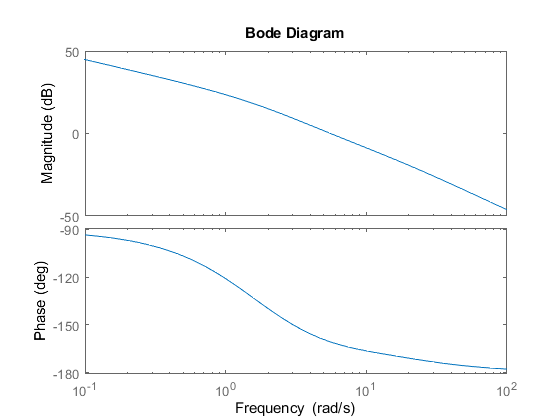

s = zpk('s');

bodeplot(G)

Number of poles in RHP of open-loop system: 1
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   1
=> Closed-loop-system is unstable


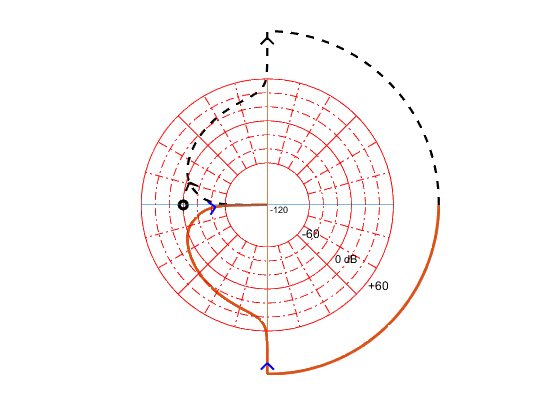

nyqlog(G)

C = 1/Gmp

C =
 
  s^4 + 24.67 s^3 + 166.8 s^2 + 211.2 s
  -------------------------------------
          s^2 + 17.4 s + 75.13
 
Continuous-time transfer function.



Controlador secundario

[b, a] = ss2tf(A, B, [0 1 0 0], 0);
roots(a)

ans =          0
  -13.3940
    9.6429
   -1.6353


roots(b)

ans = 	1.0e+-7 *

  -0.0000 + 0.9783i
  -0.0000 - 0.9783i


tf(b, a)

ans =
 
  30.06 s^2 + 1.292e-14 s + 2.877e-13
  -----------------------------------
  s^4 + 5.386 s^3 - 123 s^2 - 211.2 s
 
Continuous-time transfer function.




G2 = zpk(ss(A, B, [0 1 0 0], 0))

G2 =
 
            30.062 s
  -----------------------------
  (s+13.39) (s-9.643) (s+1.635)
 
Continuous-time zero/pole/gain model.



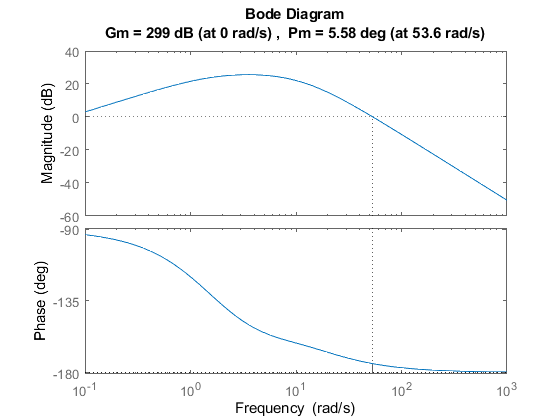

margin(100*G2)

Number of poles in RHP of open-loop system: 1
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   1
=> Closed-loop-system is unstable


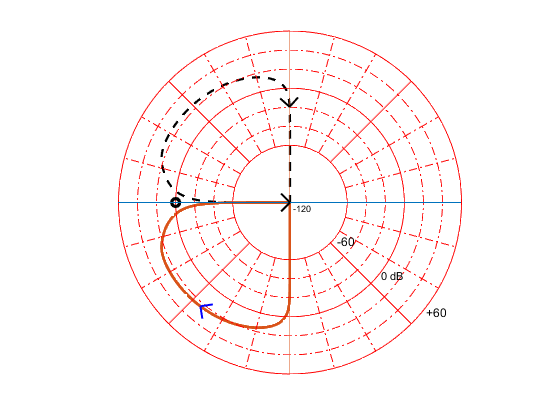

nyqlog(100*G2)

p1 = G2.P{1}(1)

p1 = -13.3940

p2 = G2.P{1}(2)

p2 = 9.6429

p3 = G2.P{1}(3)

p3 = -1.6353

z1 = 0

z1 = 0

G2mp = s / ((s-p1)*(s+p2)*(s-p3))

G2mp =
 
                s
  -----------------------------
  (s+13.39) (s+9.643) (s+1.635)
 
Continuous-time zero/pole/gain model.



G2ap = (s+p2) / (s-p2)

G2ap =
 
  (s+9.643)
  ---------
  (s-9.643)
 
Continuous-time zero/pole/gain model.



minreal(G2mp*G2ap)

ans =
 
                s
  -----------------------------
  (s+13.39) (s-9.643) (s+1.635)
 
Continuous-time zero/pole/gain model.




C2 = minreal(5000 * (s+10) * 1/s * (s+1)/(s+1000)) %PID normalizado

C2 =
 
  5000 (s+10) (s+1)
  -----------------
     s (s+1000)
 
Continuous-time zero/pole/gain model.



%C2 = 300 * (s+13.4) / (s+10*13.4)
L2 = minreal(C2*G2) 

L2 =
 
          1.5031e05 (s+10) (s+1)
  --------------------------------------
  (s+1000) (s+13.39) (s-9.643) (s+1.635)
 
Continuous-time zero/pole/gain model.



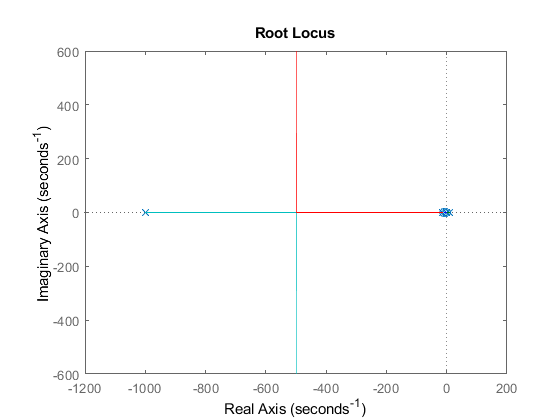

rlocus(L2)

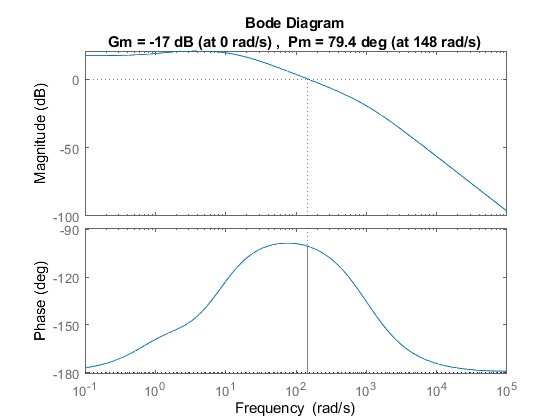

margin(L2)

diskmargin(L2)

ans = struct with fields:
           GainMargin: [0.1405 7.1165]
          PhaseMargin: [-74.0026 74.0026]
           DiskMargin: 1.5072
           LowerBound: 1.5072
           UpperBound: 1.5072
            Frequency: 0
    WorstPerturbation: [1×1 ss]


Number of poles in RHP of open-loop system: 1
Number of net encirclements around the -1 point:   -1
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


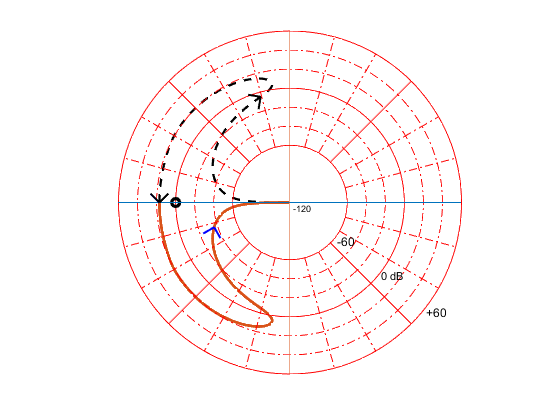

nyqlog(L2)

T = minreal(feedback(G2, C2))

T =
 
             30.062 s (s+1000)
  ---------------------------------------
  (s+817.3) (s+177.6) (s+9.55) (s+0.9321)
 
Continuous-time zero/pole/gain model.



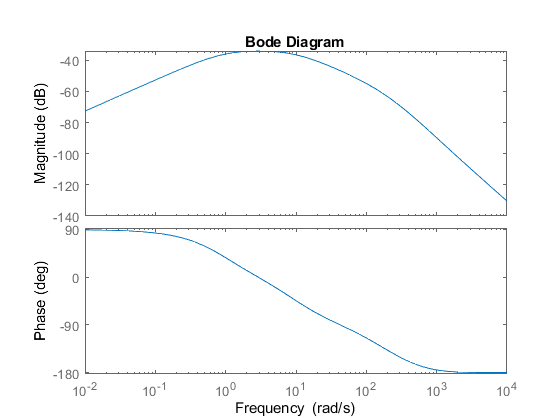

bode(T)

### Controlador primario

G = zpk(ss(A, B, [1 0 0 0; 0 1 0 0], 0))

G =
 
  From input to output...
         49.068 (s-7.941) (s+9.461)
   1:  -------------------------------
       s (s+13.39) (s-9.643) (s+1.635)
 
                 30.062 s
   2:  -----------------------------
       (s+13.39) (s-9.643) (s+1.635)
 
Continuous-time zero/pole/gain model.



G1 = G(1);
G1.InputName = 'u';
G1.OutputName = 'alpha';

G2 = G(2);
G2.InputName = 'u';
G2.OutputName = 'beta';

C2.InputName = 'beta';
C2.OutputName = 'u2';

Sum = sumblk('u = u1 - u2');

Galpha = minreal(zpk(connect(G1, G2, C2, Sum, 'u1', 'alpha')))

Galpha =
 
  From input "u1" to output "alpha":
     49.068 (s+1000) (s+9.461) (s-7.941)
  -----------------------------------------
  s (s+817.3) (s+177.6) (s+9.55) (s+0.9321)
 
Continuous-time zero/pole/gain model.



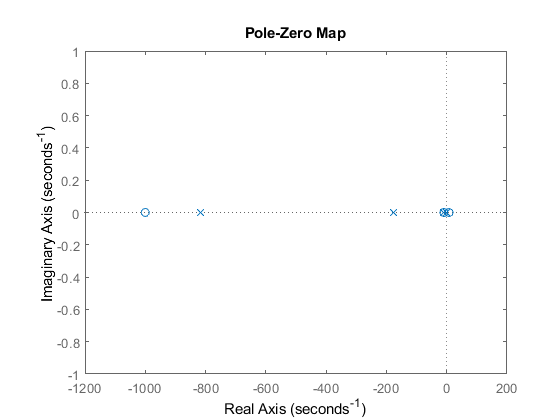

pzplot(Galpha)

z1 = Galpha.Z{1}(1)

z1 = -1.0000e+03

z2 = Galpha.Z{1}(2)

z2 = 7.9410

z3 = Galpha.Z{1}(3)

z3 = -9.4608

p1 = Galpha.P{1}(1)

p1 = -817.3300

p2 = Galpha.P{1}(2)

p2 = -177.5744

p3 = Galpha.P{1}(3)

p3 = -9.5500

p4 = Galpha.P{1}(4)

p4 = -1.9823e-14

p5 = Galpha.P{1}(5)

p5 = -0.9321

Galpha_mp = (s-z1)*(s+z2)*(s-z3) / ((s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5))

Galpha_mp =
 
        (s+1000) (s+9.461) (s+7.941)
  -----------------------------------------
  s (s+817.3) (s+177.6) (s+9.55) (s+0.9321)
 
Continuous-time zero/pole/gain model.



Galpha_ap = (s-z2)/(s+z2)

Galpha_ap =
 
  (s-7.941)
  ---------
  (s+7.941)
 
Continuous-time zero/pole/gain model.



minreal(Galpha_mp*Galpha_ap)

ans =
 
        (s+1000) (s+9.461) (s-7.941)
  -----------------------------------------
  s (s+817.3) (s+177.6) (s+9.55) (s+0.9321)
 
Continuous-time zero/pole/gain model.



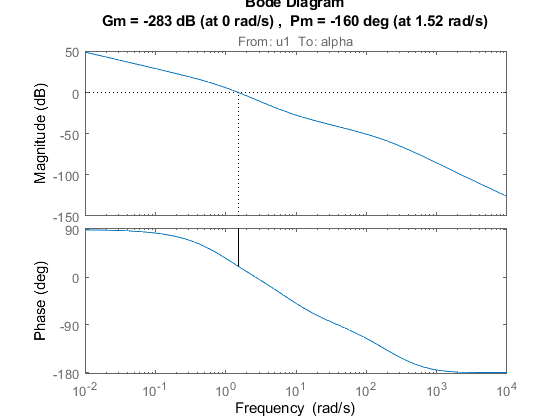

margin(Galpha)

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


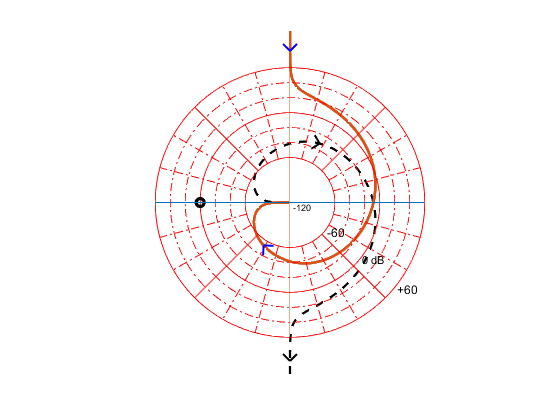

nyqlog(Galpha)

kp = 10; ki = 1; kd = 10;
%C1 = (kp + ki/s + kd*s)/(s+100);
C1=10;
L1 = minreal(C1*Galpha)

L1 =
 
  From input "u1" to output:
     490.68 (s+1000) (s+9.461) (s-7.941)
  -----------------------------------------
  s (s+817.3) (s+177.6) (s+9.55) (s+0.9321)
 
Continuous-time zero/pole/gain model.



diskmargin(L1)

ans = struct with fields:
           GainMargin: [1 1]
          PhaseMargin: [0 0]
           DiskMargin: 0
           LowerBound: 0
           UpperBound: 0
            Frequency: NaN
    WorstPerturbation: [1×1 ss]


T = feedback(Galpha, C1)

T =
 
  From input "u1" to output "alpha":
        49.068 (s+1000) (s+9.461) (s-7.941)
  ------------------------------------------------
  (s+817.5) (s+173.8) (s+9.794) (s+7.748) (s-3.42)
 
Continuous-time zero/pole/gain model.



evalfr(T, 0)

ans = 0.1000

S = 1 - T

S =
 
  From input "u1" to output "alpha":
  (s+817.5) (s+174.1) (s+9.728) (s+7.303) (s-3.28)
  ------------------------------------------------
  (s+817.5) (s+173.8) (s+9.794) (s+7.748) (s-3.42)
 
Continuous-time zero/pole/gain model.



evalfr(S, 0)

ans = 0.9000

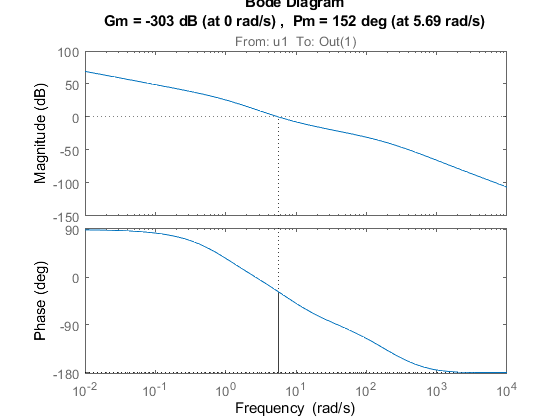

margin(L1)

Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


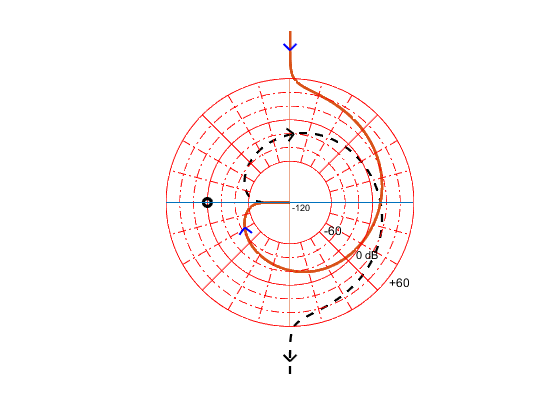

nyqlog(L1)